# Electronic Stability Control

*by Ing. Denis Efremov*

## Introduction

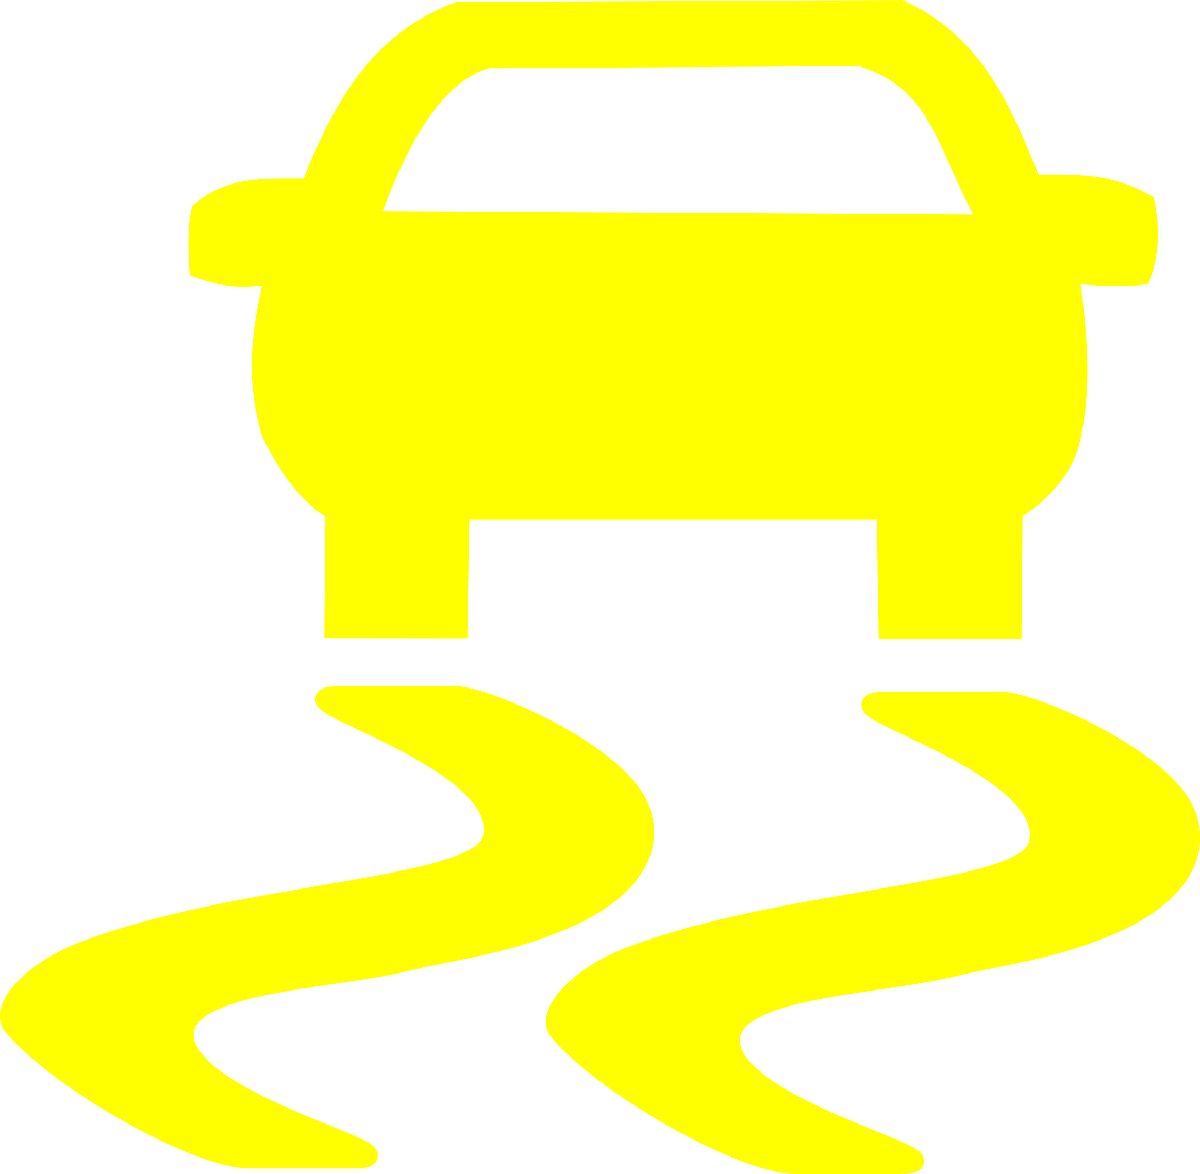Electronic stability control (ESC), also known as electronic stability program (ESP) or even dynamic stability control (DSC), is an algorithm that improves a vehicle's stability by detecting and reducing the vehicle's skidding. ESC applies brakes to help the driver to steer the car where the driver intends to go. However, other implementations can even reduce the power torques coming from the engine (or engines). Nevertheless, the idea is to generate a rotational moment around the vehicle's vertical axes comming from the center of gravity (CG) by generating different torques on different sides of the car.

In this task, we will concentrate on a basic algorithm that applies braking torque on the right or left side of the vehicle to increase the vehicle's lateral stability and improve a bit lateral vehicle controllability. 

## Modeling 

In this work, we will use the twin-track model derived in [1]. 

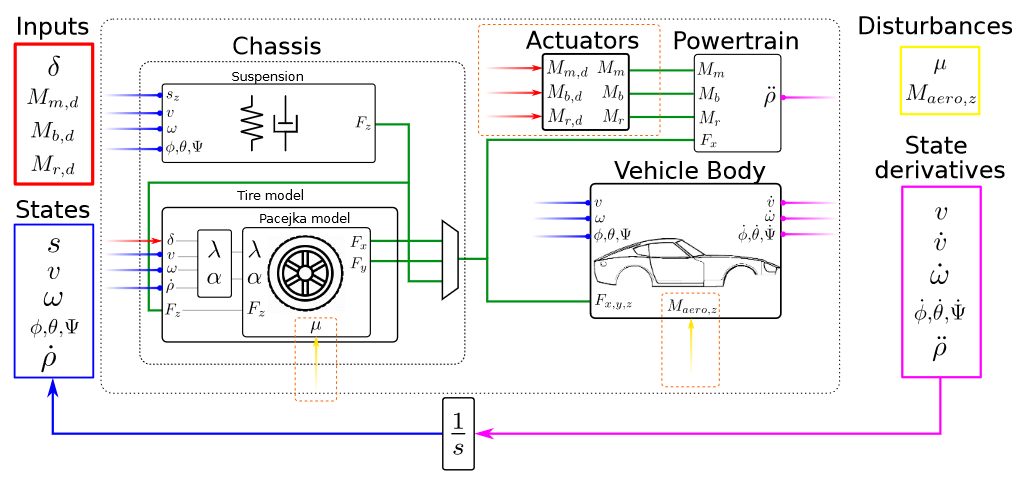 Fig.1: Twin-track model sketch [2].

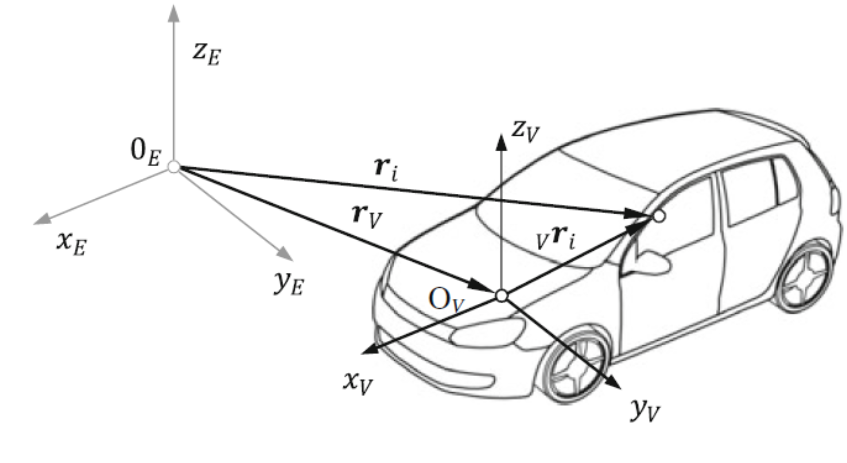Fig.2: Inertial (earth-fixed) and vehicle (body-fixed) coordinate frames [1].

The model is too complicated to provide the whole derivation here. We will concentrate on interesting values and parameters only. 

Used wheels order: (front left, front right, rear left, rear right).

The states of the system are:

- $s = [s_{\rm x}, s_{\rm y}, s_{\rm z}]$ [m, m, m], the position of the vehicle body in the earth-fixed coordinate system,

- $v = [v_{\rm x}, v_{\rm y}, v_{\rm z}]$ [m/s, m/s, m/s], the velocity of the vehicle body in the body-fixed coordinate frame,

- $\omega = [p, q, r]$ [rad/s, rad/s, rad/s], angular velocities of the vehicle body in the body-fixed coordinate system,

- $\phi, \theta, \psi$ [rad, rad, rad], roll, pitch, yaw of the vehicle (in earth-fixed coordinate frame),

- $\dot \rho$ [rad/s, rad/s, rad/s, rad/s], wheels' angular velocities.

Inputs of the system are:

- $\delta$ [rad, rad, rad, rad], steering angles of all four wheels,

- $M_{\rm m,d}$ [Nm, Nm, Nm, Nm], demanded drive torque,

- $M_{\rm b,d}$ [Nm, Nm, Nm, Nm], demanded braking torque,

- $M_{\rm r,d}$ [Nm, Nm, Nm, Nm], demanded recuperation torque (in this task, it is unused, but you may use it in your future projects).

## Problem Formulation

#### Driving experiment

The driving experiment is already well-known to you (video available *SineWithDwell.mp4*). It is sine with dwell test, which is typically provided to test the ESC functionality. The car starts the experiment moving straightly forward with high velocity (35 m/s in the experiment). Then the driver unleashes the throttle pedal and makes sine-like steering action to one side and then to the other. Then they dwell at the maximum of the sinus for a short time and return the steering wheel to the initial (neutral) position (Fig. 3).

A car without electronic stability control typically loses traction when the steering angle dwells and undergoes a skidding motion (Fig. 4). The main task of the electronic stability program is to reduce this skidding behavior, trying to follow the commanded behavior, returning the vehicle's yaw rate to zero, when the steering wheel returns to the neutral position (Fig. 5).

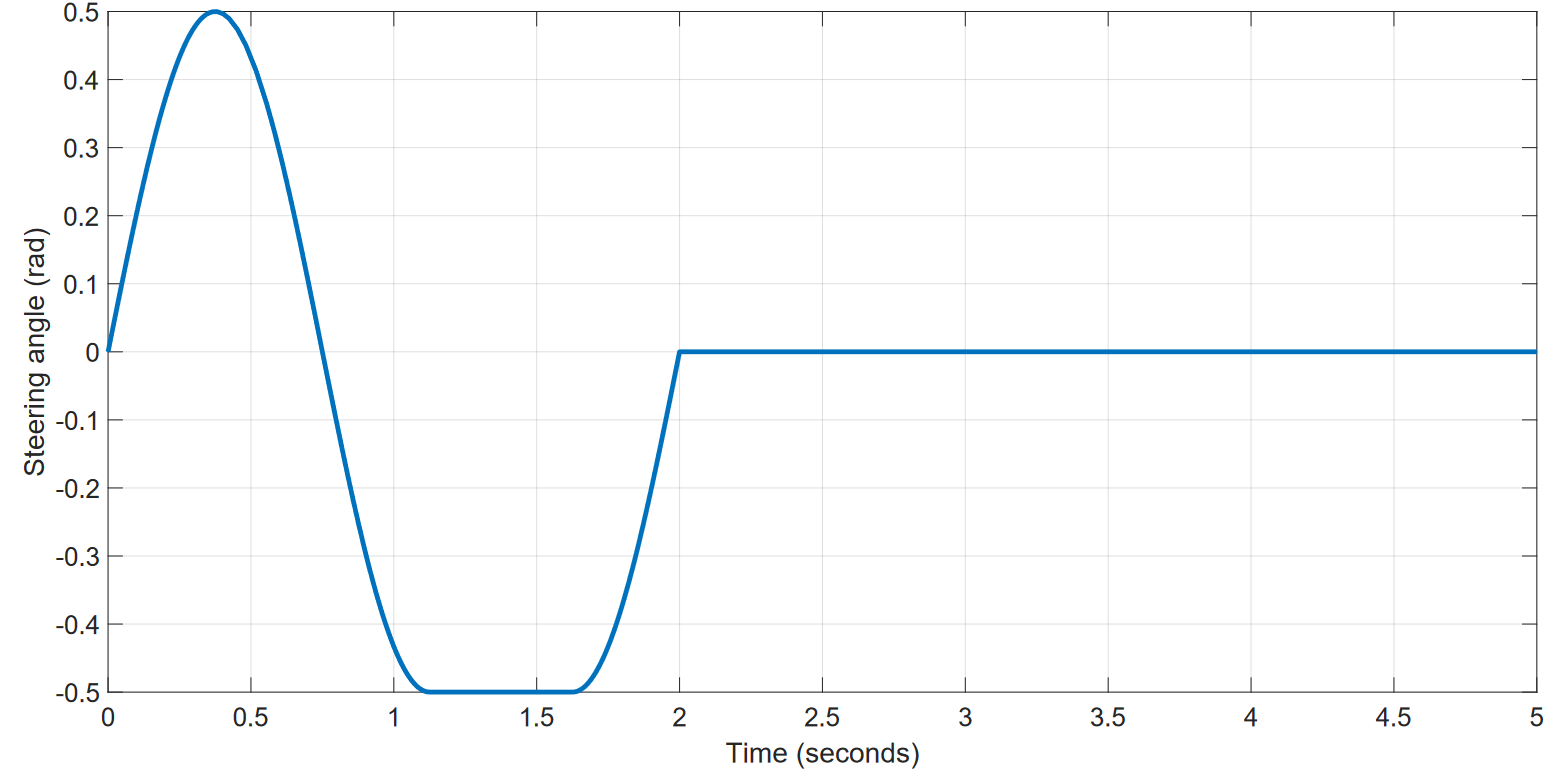Fig. 3: Steering angle during sine with dwell test.

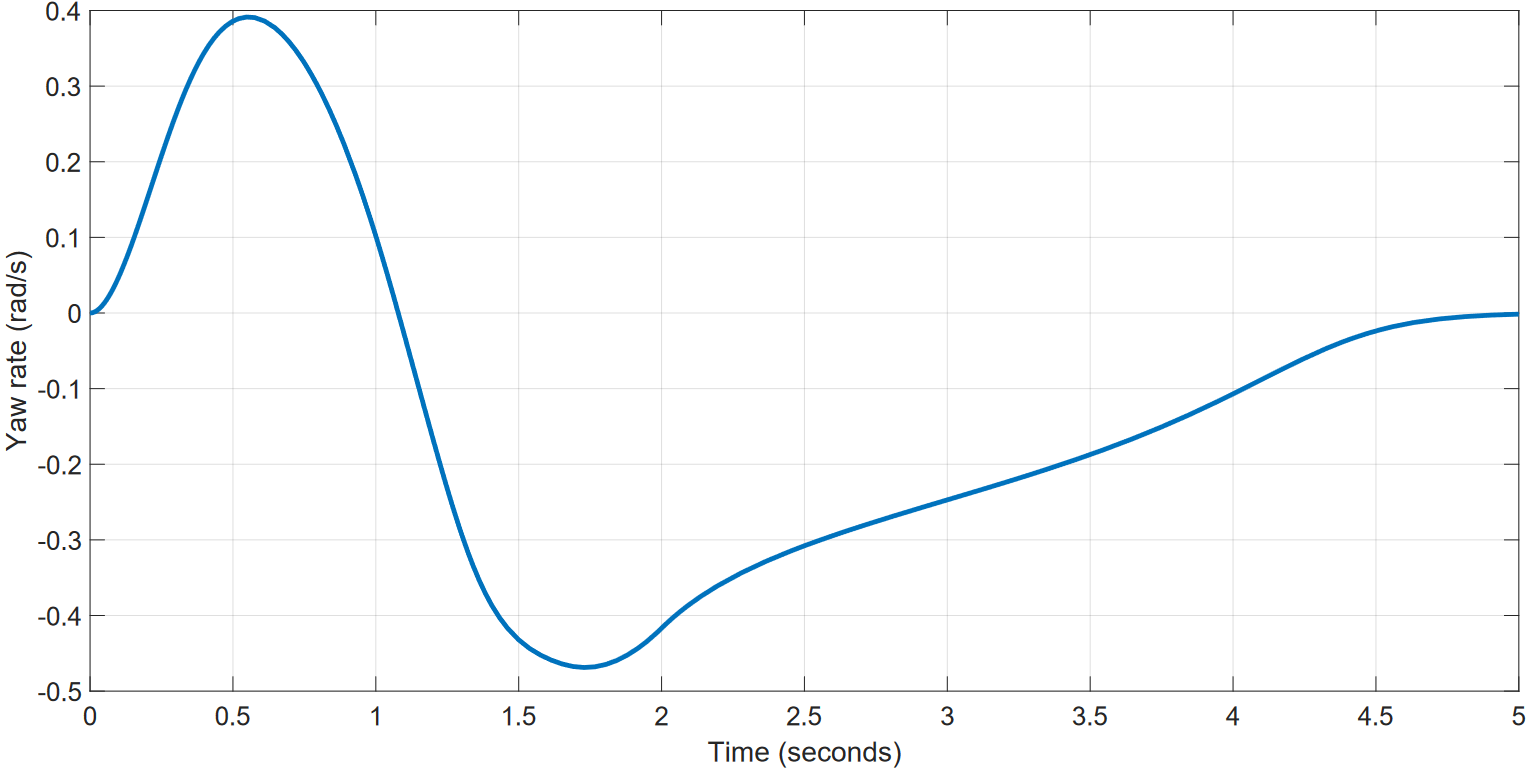Fig. 4: Yaw rate of the car without ESC during sine with dwell test.

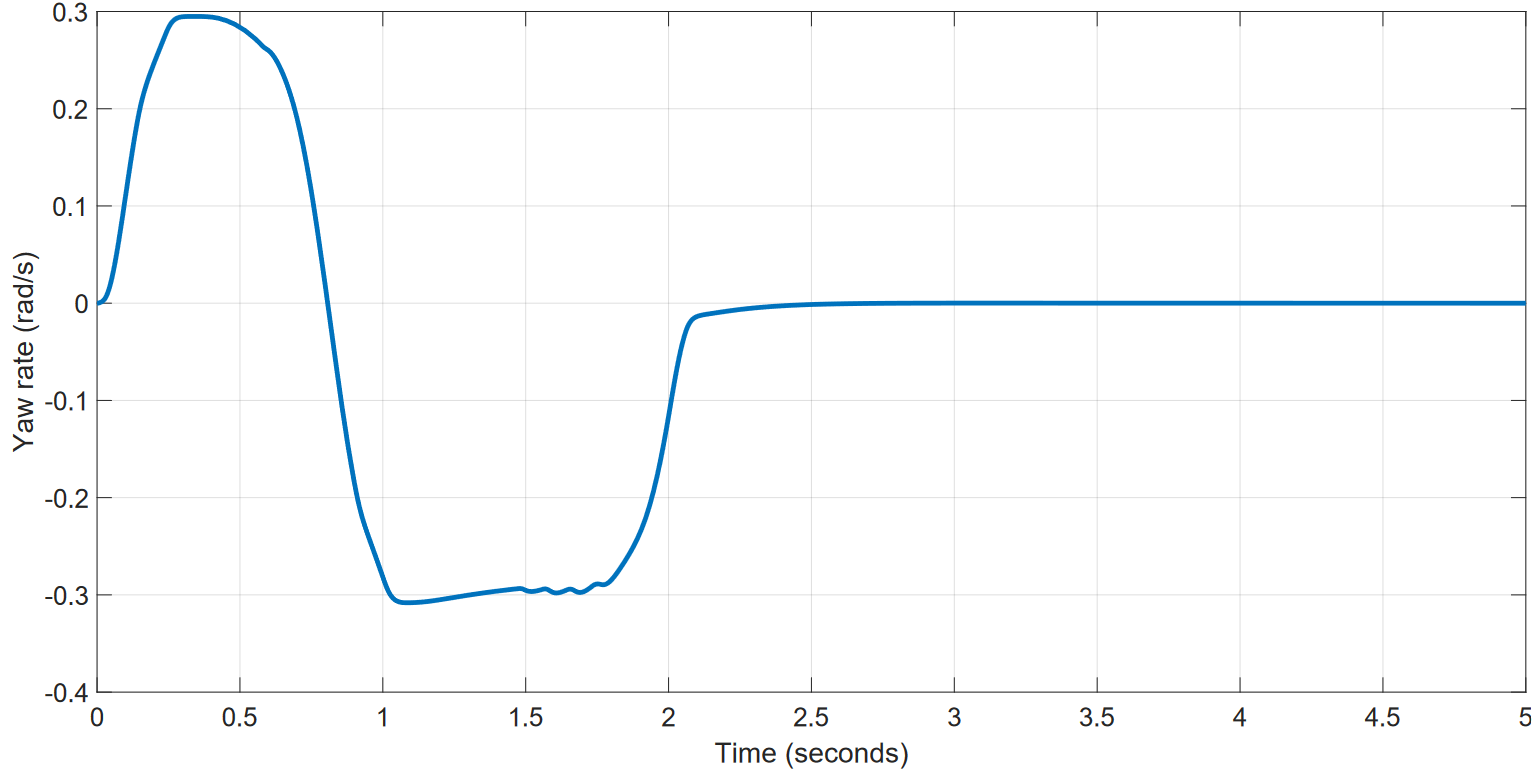Fig. 5: Yaw rate of the car with ESC during sine with dwell test.

#### Controller structure

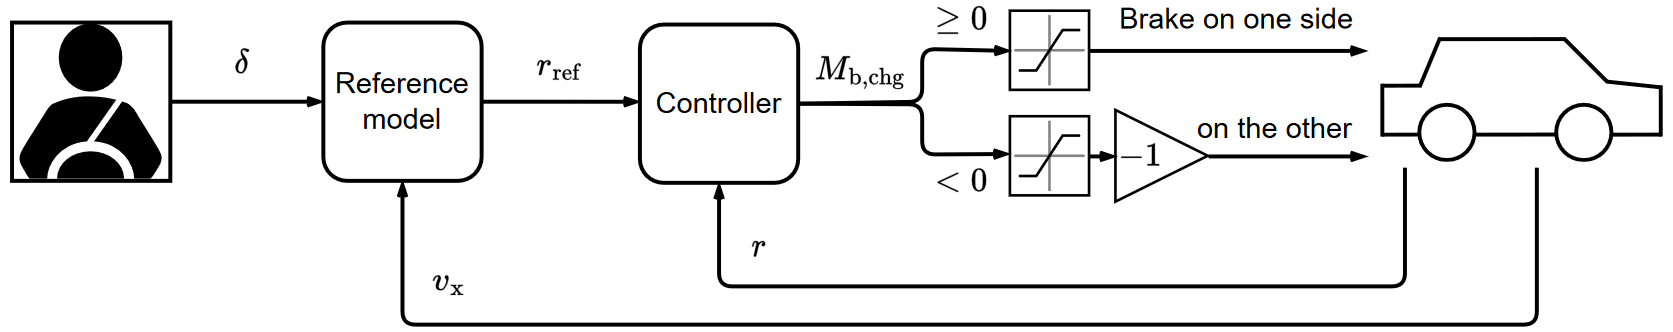Fig. 6: Electronic stability controller structure.

Typically the ESC system consists of a reference model and a controller. The reference model generates a reference for the yaw rate of a vehicle, and the controller follows the targeted yaw rate, generating a change in braking torques on one side of the car in case of positive value or on the other in case of negative value coming from the regulator.

The reference model typically consists of a kinematic model for low velocities or a dynamic model in case of higher speeds, where the kinematic model does not follow the vehicle dynamics. In our case, we will target on high speed and use a lookup table (Fig. 7) which connects steering angle, vehicle's longitudinal speed, and referenced yaw rate.

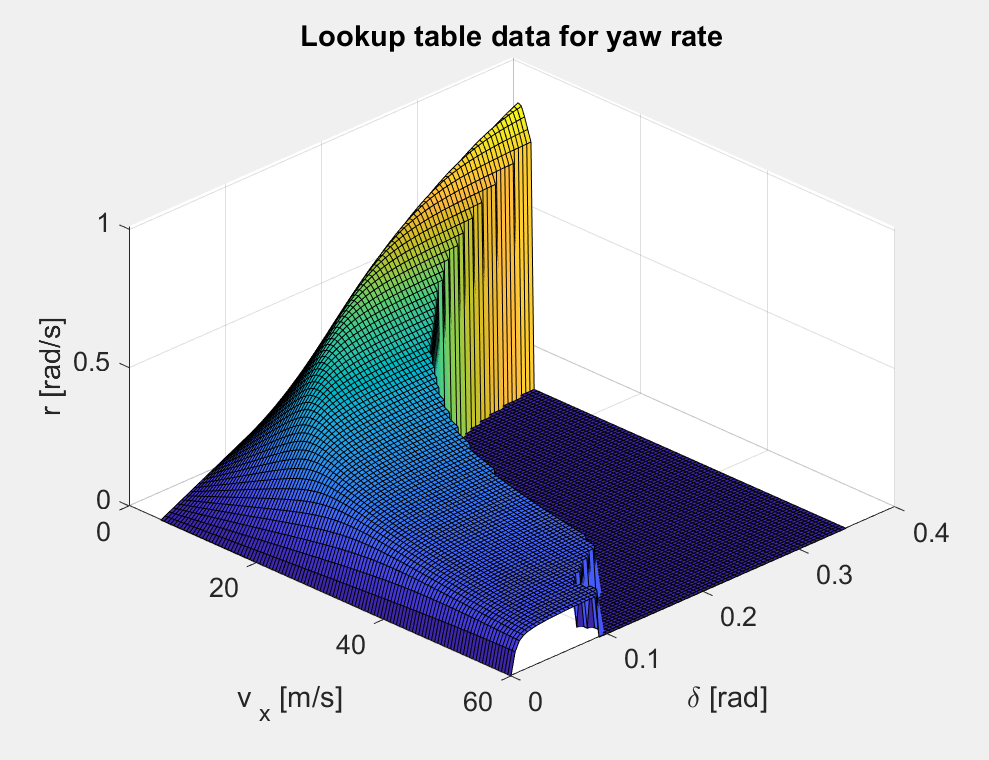

open('lookup_table.fig');

Fig. 7: Lookup table used for yaw rate reference.

The lookup table was generated by simulation the behavior of the twin-track model for a given velocity and steering angle for a significantly long period of time (20 seconds). Values in plateau refer to undesired vehicle behavior, where the simulated model lost traction at least on one wheel (see section 2.2.2 in [2] for details).

## Implementation of the Controller

1) Get familiar with the Simulink model *ESC_sim.slx*. Run initializing script *runme.m* before running the simulation. The lookup table is already implemented there.

2) Implement a controller structure that will generate brake torque change and apply it on one or other side depending on the value of the computed change.

3) Find an appropriate structure for the controller and tune it. We suggest you start with a regular P controller and adjust it with an iterative method. Or you can provide a linearization of the model from a sum of braking torques coming from one side of the vehicle to yaw rate using the linmod function in Matlab to suggest a good controller candidate based on your knowledge of the automatic control theory.

## References

[1] Cibulka, V. (2019). Mpc based control algorithms for vehicle control. Master’s thesis, Czech Technical University in Prague.

[2] Halaška, L. (2020). Vehicle electronic stabilization system development. Bachelor’s thesis, Czech Technical University in Prague